% .... Displacement mm 
D = [0 10 20 30 40 50 60 70 80 100]

D =      0    10    20    30    40    50    60    70    80   100


% .... Stress Mpa 
sigm = [78.2 74.8 73.4 71.6 70.2 68.5 66.7 64.4 63.2 59.3]  

sigm =    78.2000   74.8000   73.4000   71.6000   70.2000   68.5000   66.7000   64.4000   63.2000   59.3000


sigma = sigm + 4;
nD = length (D);
syms x 
[L, polynomial, simply2] = interpolation (D, sigma, nD, x) 

$$simply2 = -\frac{601\,x^{9}}{7257600000000000}+\frac{29\,x^{8}}{840000000000}-\frac{73291\,x^{7}}{12096000000000}+\frac{2099\,x^{6}}{3600000000}-\frac{46333\,x^{5}}{1382400000}+\frac{2639\,x^{4}}{2250000}-\frac{44097251\,x^{3}}{1814400000}+\frac{345361\,x^{2}}{1260000}-\frac{194149\,x}{126000}+\frac{411}{5}$$

xx = 0: 5: 100 ;
length_x = length (xx) ;

for i = 1: length_x 
sigmaint_g (i) = subs (simply2, x,  xx (i));  
end 
for i  =1: length (polynomial)
for j = 1: length_x 
polinom_z(i,j) = subs (polynomial (i), x, xx (j));  
end 
end 
polinom_z

simply2 

$$simply2 = -\frac{601\,x^{9}}{7257600000000000}+\frac{29\,x^{8}}{840000000000}-\frac{73291\,x^{7}}{12096000000000}+\frac{2099\,x^{6}}{3600000000}-\frac{46333\,x^{5}}{1382400000}+\frac{2639\,x^{4}}{2250000}-\frac{44097251\,x^{3}}{1814400000}+\frac{345361\,x^{2}}{1260000}-\frac{194149\,x}{126000}+\frac{411}{5}$$

polinom_z 

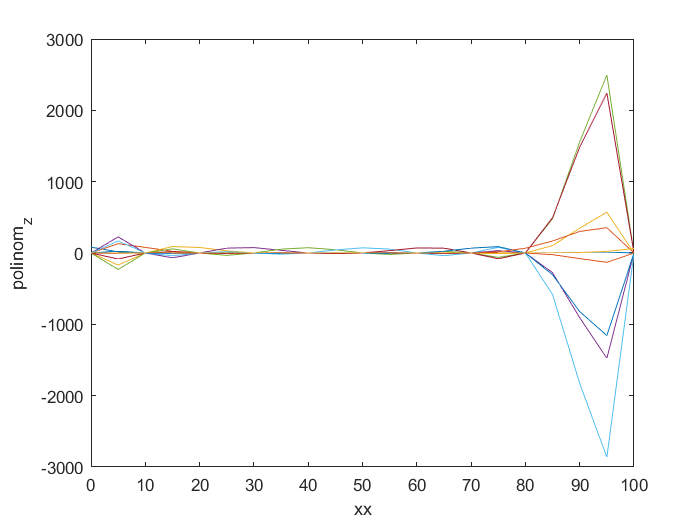

L;  
plot (xx, polinom_z);  
xlabel ('xx');  
ylabel ('polinom_z');  

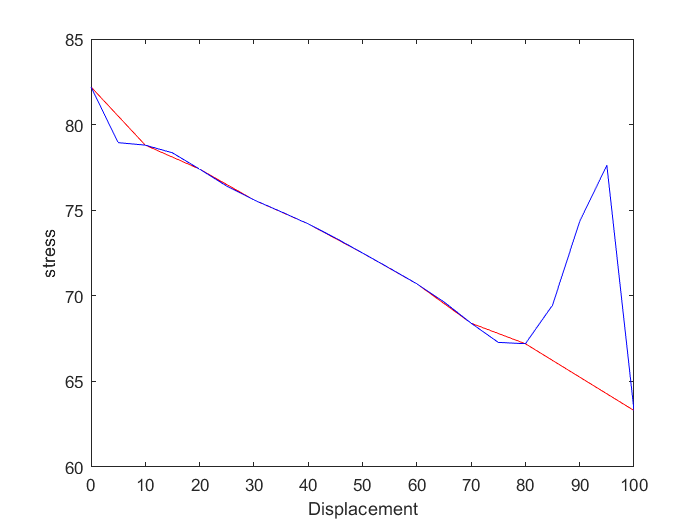

figure;  
sigmaint_g;  
plot (D, sigma, '-r ', xx, sigmaint_g,' b ');
xlabel ('Displacement');  
ylabel ('stress');

figure;
p=polyfit(D,sigma,1) 

p =    -0.1797   81.2981


f=polyval(p,D) 

f =    81.2981   79.5006   77.7032   75.9058   74.1084   72.3110   70.5136   68.7162   66.9188   63.3240


table=[D;sigma;f;sigma-f] 

table =          0   10.0000   20.0000   30.0000   40.0000   50.0000   60.0000   70.0000   80.0000  100.0000
   82.2000   78.8000   77.4000   75.6000   74.2000   72.5000   70.7000   68.4000   67.2000   63.3000
   81.2981   79.5006   77.7032   75.9058   74.1084   72.3110   70.5136   68.7162   66.9188   63.3240
    0.9019   -0.7006   -0.3032   -0.3058    0.0916    0.1890    0.1864   -0.3162    0.2812   -0.0240


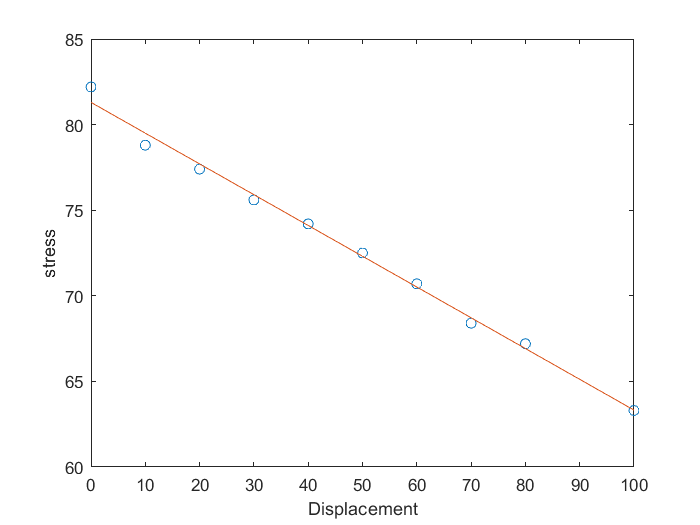

plot(D,sigma,'o',D,f,'-'); 
xlabel ('Displacement');  
ylabel ('stress');